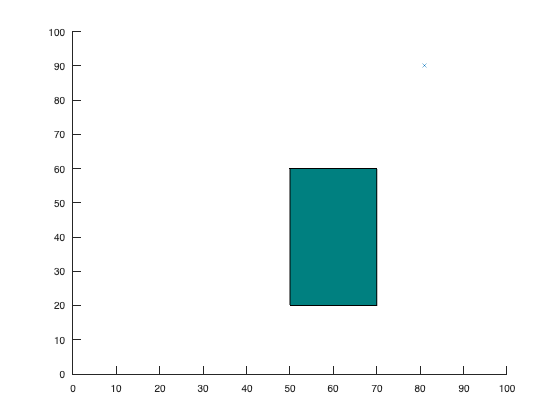

dist requires one of the following:
  Aerospace Toolbox
  Deep Learning Toolbox
  Automated Driving Toolbox
  Sensor Fusion and Tracking Toolbox
  Navigation Toolbox
  Radar Toolbox
  

% nodes:    Contains list of all explored nodes. Each node contains its
%           coordinates, cost to reach and its parent.
%
% Brief description of first use of RRT* algorithm:
% 1. Pick a random node q_rand.
% 2. Find the closest node q_near from explored nodes to branch out from, towards
%    q_rand.
% 3. Steer from q_near towards q_rand: interpolate if node is too far away, reach
%    q_new. Check that obstacle is not hit.
% 4. Update cost of reaching q_new from q_near, treat it as Cmin. For now,
%    q_near acts as the parent node of q_new.
% 5. From the list of 'visited' nodes, check for nearest neighbors with a
%    given radius, insert in a list q_nearest.
% 6. In all members of q_nearest, check if q_new can be reached from a
%    different parent node with cost lower than Cmin, and without colliding
%    with the obstacle. Select the node that results in the least cost and
%    update the parent of q_new.
% 7. Add q_new to node list.
% 8. Continue until maximum number of nodes is reached or goal is hit.

%% using stays for part that have no problem from the get go 

%%stays 
%Creating graph and obstacle
x_max = 100;
y_max = 100;
obstacle = [50,20,20,40];
EPS = 2;
numNodes = 1000;

%%stays 
%Arbitrarly choosing start and goal nodes
q_start.coord = [0 0];
q_start.cost = 0;
q_start.parent = 0;%% check implications %%%%%%%%%%%%%%%%%
q_goal.coord = [99 99];
q_goal.cost = 0;

%Creating figure for visualization
nodes(1) = q_start;
figure(1)
axis([0 x_max 0 y_max])
rectangle('Position',obstacle,'FaceColor',[0 .5 .5])
hold on

%Creating empty cell array in which path points will be added to
pathT = {};

%check 1. pick random node q_rand. %Selecting random node
for i = 1:1:numNodes
    q_rand = [floor(rand(1)*x_max) floor(rand(1)*y_max)];
    plot(q_rand(1), q_rand(2), 'x', 'Color',  [0 0.4470 0.7410])

    % Break if goal node is already reached
    for j = 1:1:length(nodes)
        if nodes(j).coord == q_goal.coord
            break
        end
    end


    % Pick the closest node from existing list to branch out from
    ndist = [];
    for j = 1:1:length(nodes)
        n = nodes(j);
        tmp = dist(n.coord, q_rand);
        ndist = [ndist tmp];
    end
    [val, idx] = min(ndist);
    q_near = nodes(idx);

    %Checking if there is a collision with obstacle between random node and nearest coordinate
    q_new.coord = steer(q_rand, q_near.coord, val, EPS);
    if noCollision(q_rand, q_near.coord, obstacle)
        line([q_near.coord(1), q_new.coord(1)], [q_near.coord(2), q_new.coord(2)], 'Color', 'k', 'LineWidth', 2);
        drawnow
        hold on
        q_new.cost = dist(q_new.coord, q_near.coord) + q_near.cost;
        q_nearest = [];
        % Within a radius of r, find all existing nodes
        r = 20;
        neighbor_count = 1;
        for j = 1:1:length(nodes)
            if noCollision(nodes(j).coord, q_new.coord, obstacle) <=r && dist(nodes(j).coord, q_new.coord) <= r
                q_nearest(neighbor_count).coord = nodes(j).coord;
                q_nearest(neighbor_count).cost = nodes(j).cost;
                neighbor_count = neighbor_count+1;
            end
        end





        % Initialize cost to currently known value
        q_min = q_near;
        C_min = q_new.cost;

        % Iterate through all nearest neighbors to find alternate lower
        % cost paths
        for k = 1:1:length(q_nearest)
            if noCollision(q_nearest(k).coord, q_new.coord, obstacle) && q_nearest(k).cost + dist(q_nearest(k).coord, q_new.coord) < C_min
                q_min = q_nearest(k);
                C_min = q_nearest(k).cost + dist(q_nearest(k).coord, q_new.coord);
                line([q_min.coord(1), q_new.coord(1)], [q_min.coord(2), q_new.coord(2)], 'Color', 'g');
                hold on
            end
        end

        % Update parent to least cost-from node
        for j = 1:1:length(nodes)
            if nodes(j).coord == q_min.coord
                q_new.parent = j;
            end
        end

        % Append to nodes
        nodes = [nodes q_new];
    end
end